# Shapiro-Wilks test for Normality

clc,clear,close all
data = readtable('C:\Users\Nathan\OneDrive\Documents\Liberty\2025-2026\Capstone\Code\DistributionTest.csv');
darray=table2array(data(:,"raw_distance_mm"))

darray =         1432
        1446
        1446
        1440
        1454
        1451
        1439
        1451
        1437
        1448


[h,p] = jbtest(darray)

h = 0

p = 0.1356

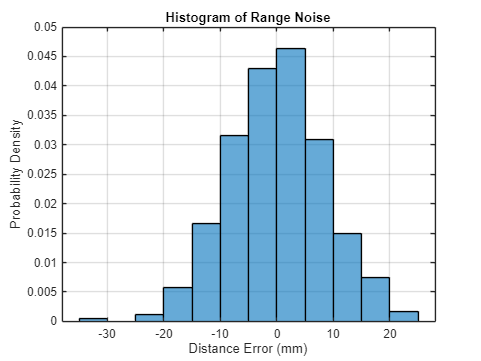



darray = darray(50:end);
data = darray - mean(darray);
figure;
histogram(data,'Normalization','pdf');
grid on;
xlabel('Distance Error (mm)');
ylabel('Probability Density');
title('Histogram of Range Noise');

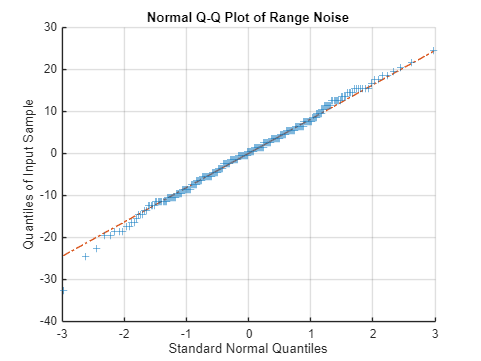


figure;
qqplot(data);
grid on;
title('Normal Q-Q Plot of Range Noise');